# Computer Assignment 1

## 1. Normalization

Consider an optimization problem of the form


$$\min f(\mathbf{x}) = (\mathbf{x}-\mathbf{c})^\top A (\mathbf{x}-\mathbf{c})\\
\; \:\mathrm{s.t.} \; \mathbf{x},\mathbf{c} \in \mathbb{R}^2 ,$$


with $A = \left[ \matrix{3\cdot 10^{-12} & 10^{-6} \cr 10^{-6} & 1} \right] $ and $\mathbf{c} = \left[\matrix{2\cdot 10^6 \cr 1} \right]$. Find the optimum analytically and then with the $\textit{grad\_descent}$ function below.

A = [3e-12,1e-6;1e-6,1];
c = [2e6;1];

% Solve with gradient descent algorithm
format long;
tic;
[x,nit,x_iter] = grad_descent(A,c,[0;0],1e4); % grad_descent(A,c,initial condition,max iterations)
toc

Elapsed time is 0.011592 seconds.



x

x =    0.079999998399840
   0.000000039998238


nit

nit =        10001


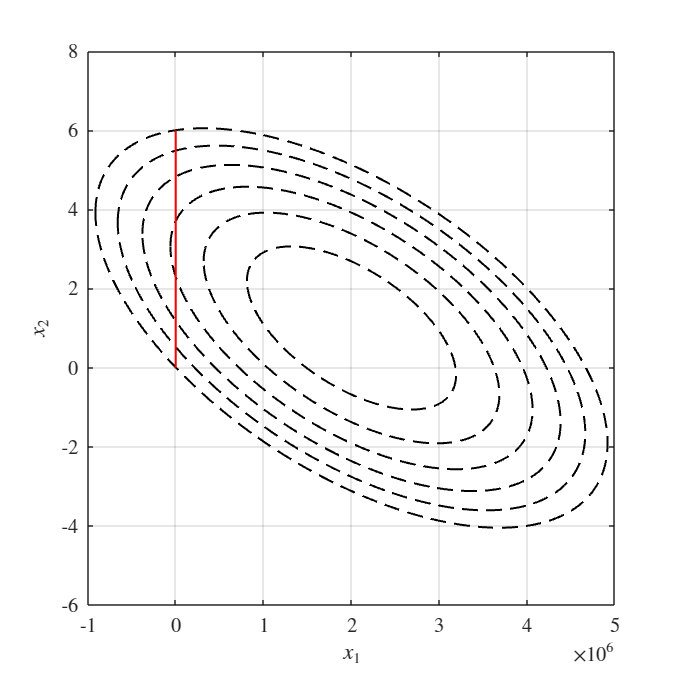

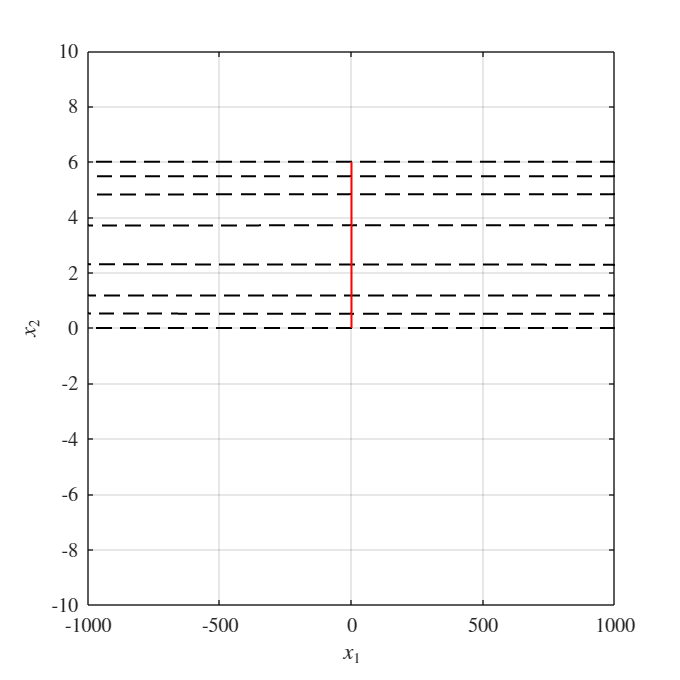


% Plot gradient descent iterations
grad_descent_plot(A,c,nit,x_iter,1);

- Is the problem convex? Why?

- Does the analytical result match the numerical results from the function? If not, why and can you improve the numerical results? (Hint: Play around with the initial conditions and the maximum number of iterations)

- Determine the number of iterations and the time required by the $\textit{grad\_descent}$ function to find the minimum (Hint: Stop if it is taking more than a minute).

Now see if you can find a faster solution (Hint: you do not need to change the algorithm).

% Normalize
A_n = diag([c(1) c(2)])*A*diag([c(1) c(2)]);
c_n = [1;1];

tic;
[z,nit,z_iter] = grad_descent(A_n,c_n,[0;0],1e4);
toc

Elapsed time is 0.002703 seconds.



z

z =    1.000000388465225
   0.999999818716228


nit

nit =    144



% Unnormalize
x = diag(c(1),c(2))*z;
fprintf("x_1 = %.0f, x_2 = %.0f",z(1)*c(1),z(2)*c(2))

x_1 = 2000001, x_2 = 1

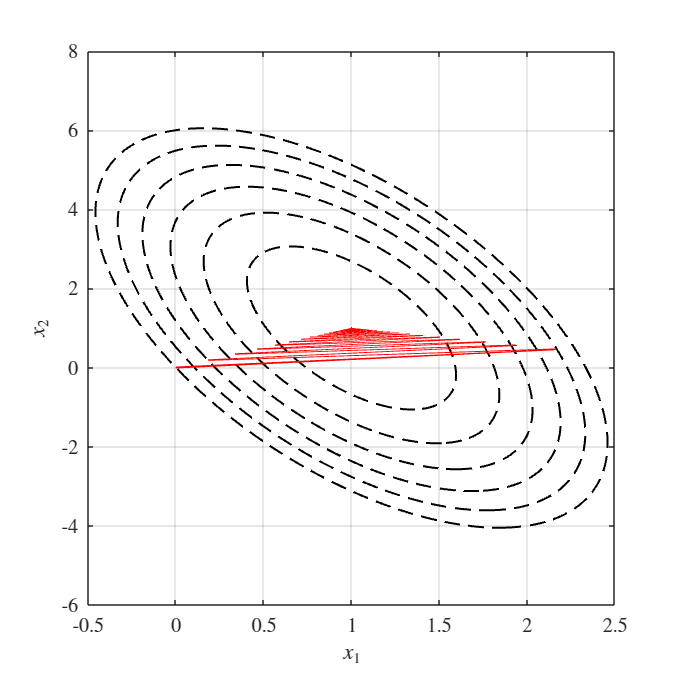


% Plot gradient descent iterations
grad_descent_plot(A_n,c_n,nit,z_iter,0);

How did you do it? How has the runtime improved compared to before?

## 2. Design problem

a) Plot the contour plot of the optimization problem with the code below. Explain how the Matlab code works.

b) Identify in the plot the objective function contour lines and the constraint contour.

c) Identify in the plot the feasible domain and the location of the minimizer. Which constraints are active? Which constraints are dominated?

d) Verify the convexity of the objective function and the constraints (Hint: see Exercise 4 of Exercises and Study Questions 1). Is the optimization problem convex over χ? And how about the convexity of feasible domain spanned by the active constraints?

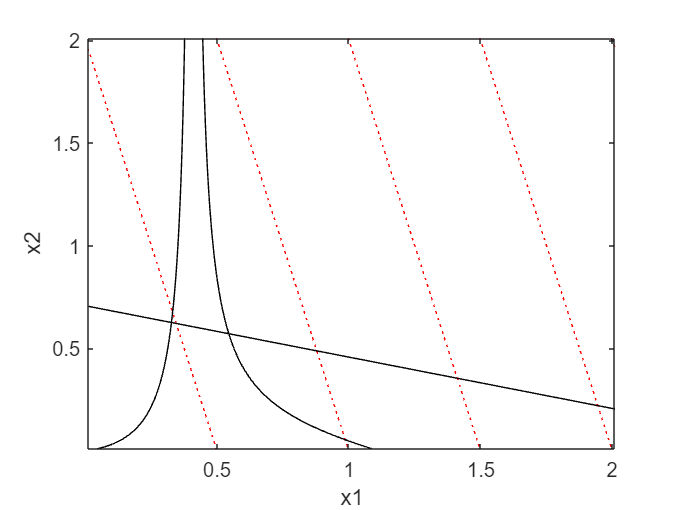

clear;

% Compute matrices of objective function and constraint function values 
% for combinations of x1 and x2
x1vec = [0.01:0.01:2.01];
x2vec = [0.01:0.01:2.01];
for j=1:1:length(x2vec)
  for i=1:1:length(x1vec)

    % Doint in design space
    x1=x1vec(i); x2=x2vec(j);
   
    % Dimensionless stresses in bars 1,2, and 3
    f1 = 0.5*sqrt(2)*( (sqrt(3)/(3*x1)) + 1/(x1+4*x2) );
    f2 = 2*sqrt(2)/(x1+4*x2);
    f3 = 0.5*sqrt(2)*( (-sqrt(3)/(3*x1)) + 1/(x1+4*x2) );
    
    % Objective function (mass)
    F(j,i) = 4*x1 + x2; 

    % Tensile stress contraints
    g1(j,i) = f1 - 1;
    g2(j,i) = f2 - 1;
    g3(j,i) = f3 - 1;

    % Compression stress contraints
    g4(j,i) = -f1 - 1;
    g5(j,i) = -f2 - 1;
    g6(j,i) = -f3 - 1;
   
  end
end
figure();
contour(x1vec,x2vec, F, [2 4 6 8 10],'r:')
xlabel('x1'), ylabel('x2')
set(gca,'Xtick',[0.5:0.5:2])
set(gca,'Ytick',[0.5:0.5:2])
hold on
contour(x1vec, x2vec, g1, [0 0], 'k-')
contour(x1vec, x2vec, g2, [0 0], 'k-')
contour(x1vec, x2vec, g3, [0 0], 'k-')
contour(x1vec, x2vec, g4, [0 0], 'k-')
contour(x1vec, x2vec, g5, [0 0], 'k-')
contour(x1vec, x2vec, g6, [0 0], 'k-')

e) Solve the three-bar truss design problem using fmincon. Compare the outcome with the plot. Which constraints are active at the minimizer?


options = optimoptions('fmincon');
options = optimoptions(options,'Display','Iter');

% Initial guess
x0 = [2.0 2.0];

% Lower and upper bounds
lb = [0.00001 0.00001];
ub = [inf inf];

% Optimize
x = fmincon(@objfunGS1,x0,[],[],[],[],lb,ub,@confunGS1,options)
% Plot solution
scatter(x(1),x(2),100,'*','LineWidth',2)

function f = objfunGS1(x)
    % Objective function for Guided Selfstudy Assignment 1, question g) 
    
    % Design variable values
    x1 = x(1);
    x2 = x(2);
    
    % Objective function
    f = 4*x1 + x2;
end

function [g,h] = confunGS1(x)
    % Constraint functions for Guided Selfstudy Assignment 1, question g) 
    
    % Design variables
    x1 = x(1);
    x2 = x(2);
    
    % Stresses
    s1 = 0.5*sqrt(2)*(sqrt(3)./(3*x1) + 1./(x1+4*x2));
    s2 = 2*sqrt(2)./(x1+4*x2);
    s3 = 0.5*sqrt(2)*(-sqrt(3)./(3*x1) + 1./(x1+4*x2));
    
    % Constraints
    g(1) = s1 - 1; 
    g(2) = s2 - 1; 
    g(3) = s3 - 1; 
    g(4) = -s1 - 1; 
    g(5) = -s2 - 1; 
    g(6) = -s3 - 1; 
    h = [];
end


## Axiliary functions

function [x_out,niter,x] = grad_descent(A,c,x0,maxiter)
% Define functions
f1 = @(x1,x2) ([x1;x2]-c)'*A*([x1;x2]-c);
f2 = @(x) (x-c)'*A*(x-c);
grad = @(x) 2*A*(x-c);
% Optimal step size
step = 1/(max(eig(A))+min(eig(A)));
% Tolerance
tol = 1e-5;
% Initialize
x = zeros(2,maxiter);
gnorm = inf;
x(:,1) = x0;
niter = 1;
% Gradient descent algorithm
while gnorm >=tol && niter <= maxiter
    % calculate gradient:
    g = grad(x(:,niter));
    gnorm = norm(g);
    % take step:
    x(:,niter+1) = x(:,niter) - step*g;
    niter = niter+1;
end
x_out = x(:,niter);
end

function grad_descent_plot(A,c,nit,x_iter,flag)
    % Define functions
    f1 = @(x1,x2) ([x1;x2]-c)'*A*([x1;x2]-c);
    f2 = @(x) (x-c)'*A*(x-c);
    grad = @(x) 2*A*(x-c);
    % Level curves
    Ncurves = 7;
    Npoints = 1000;
    costs = 0:f1(0,0)/(Ncurves-1):f1(0,0);
    theta = 0:2*pi/(Npoints-1):2*pi;
    y = zeros(2,Npoints);
    x = zeros(2,Npoints);
    y(1,:) = cos(theta);
    y(2,:) = sin(theta);
    [S,D] = eig(A);
    T = inv(sqrtm(D)*inv(S));
    for i = 1:Npoints
        x(:,i) = T*y(:,i);
    end

    % Plot level curves and iterations
    figure('Position',4*[0 0 144 144]);
    hold on;
    grid on;
    box on;
    % set(gca,'FontSize',20);
    set(gca,'TickLabelInterpreter','latex');
    for i = 1:Ncurves
        plot(c(1)+sqrt(costs(i))*x(1,:),c(2)+sqrt(costs(i))*x(2,:),'--k','LineWidth',1);
    end
    plot(x_iter(1,1:nit),x_iter(2,1:nit),'-r','LineWidth',1);
    ylabel('$x_2$','Interpreter','latex');
    xlabel('$x_1$','Interpreter','latex');
    hold off;

    if flag 
    % Plot level curves and iterations
    figure('Position',4*[0 0 144 144]);
    hold on;
    grid on;
    box on;
    % set(gca,'FontSize',20);
    set(gca,'TickLabelInterpreter','latex');
    for i = 1:Ncurves
        plot(c(1)+sqrt(costs(i))*x(1,:),c(2)+sqrt(costs(i))*x(2,:),'--k','LineWidth',1);
    end
    plot(x_iter(1,1:nit),x_iter(2,1:nit),'-r','LineWidth',1);
    ylabel('$x_2$','Interpreter','latex');
    xlabel('$x_1$','Interpreter','latex');
    ylim([-1 1]*10);
    xlim([-1 1]*1e3);
    hold off;
    end

end

